%1
clear all
load('Dell.mat');
load('Inkjet.mat');

plot_chrom(XYZdell,'r')
plot_chrom(XYZinkjet,'b')
%Inkjet is not good at representing colour but also, the inkjet printer
%doesn't use rgb values so of course the representation in the gamut is
%going to be different. We can for example clearly see the yellow
%representation in the inkjet printers gamut.

%2.1.1
im = imread('peppers_gray.tif');
im = im2double(im);

near = imresize(imresize(im,0.25,'nearest'),4,'nearest');
biline = imresize(imresize(im,0.25,'bilinear'),4,'bilinear');
bicube = imresize(imresize(im,0.25,'bicubic'),4,'bicubic');

imshow(near)
imshow(biline)
imshow(bicube)

MSE_near = immse(near,im);
MSE_biline = immse(biline,im);
MSE_bicube = immse(bicube,im);
%near is worst and we agree with that

%2.1.2
im_thresh = double(im>=0.5);

imshow(im_thresh)

MSE_thresh = immse(im_thresh, im);

im_dither = double(dither(im));

imshow(im_dither)

MSE_dither = immse(im_dither, im);

%Don't really understand the question, do you mean that we should compare
%them to before or that we should do it with a different value for the
%threshold? Either way we don't really agree honestly. Dither to us looks
%better than for example near, better representing the original image, but
%this doesn't correlate to the results of the mse calculations.

%2.2
im2 = imread('peppers_color.tif');
im2 = im2double(im2);

imLab = rgb2lab(im2);
%imshow(imLab);

im2_thresh = double(im2>=0.5);

imshow(im2_thresh)

im2_dither(:,:,1) = double(dither(im2(:,:,1)));
im2_dither(:,:,2) = double(dither(im2(:,:,2)));
im2_dither(:,:,3) = double(dither(im2(:,:,3)));

imshow(im2_dither)

im2_thresh_lab = rgb2lab(im2_thresh);
im2_lab = rgb2lab (im2);

diff = sqrt((im2_thresh_lab(:,:,1)-im2_lab(:,:,1)).^2 +(im2_thresh_lab(:,:,2)-im2_lab(:,:,2)).^2 +((im2_thresh_lab(:,:,3)-im2_lab(:,:,3)).^2));
maxVal = max(max(diff));
meanVal = mean(mean(diff));

im2_dither_lab = rgb2lab(im2_dither);

diff2 = sqrt((im2_dither_lab(:,:,1)-im2_lab(:,:,1)).^2 +(im2_dither_lab(:,:,2)-im2_lab(:,:,2)).^2 +((im2_dither_lab(:,:,3)-im2_lab(:,:,3)).^2));
maxVal2 = max(max(diff2));
meanVal2 = mean(mean(diff2));

%dithered is somehow worse than threshold, does not align with out own
%judgement of what is the best looking.

%3

thresh_noise = (im - im_thresh);
hvs_thresh = snr_filter(im, thresh_noise);


dither_noise = (im - im_dither);
hvs_dither = snr_filter(im_dither,dither_noise);

%SNR higher is better

%3.b
im2 = im2double(imread('peppers_color.tif'));
im2_lab = rgb2lab(im2);


im2_hvs = rgb_filter(im2);
im2_thresh_hvs = rgb_filter(im2_thresh);
im2_dither_hvs = rgb_filter(im2_dither);

im2_hvs_lab = rgb2lab(im2_hvs);
im2_thresh_hvs_lab = rgb2lab(im2_thresh_hvs);
im2_dither_hvs_lab = rgb2lab(im2_dither_hvs);

subplot(1,4,1), imshow(im2);
subplot(1,4,2), imshow(im2_hvs);
subplot(1,4,3), imshow(im2_thresh_hvs);
subplot(1,4,4), imshow(im2_dither_hvs);

diff_thresh_hsv = sqrt(sum((im2_thresh_hvs_lab - im2_hvs_lab) .^ 2, 3));
diff_dither_hsv = sqrt(sum((im2_dither_hvs_lab - im2_hvs_lab) .^ 2, 3));

diff_thresh_hsv_max = max(diff_thresh_hsv(:));
diff_thresh_hsv_mean = mean(diff_thresh_hsv(:));
diff_dither_hsv_max = max(diff_dither_hsv(:));
diff_dither_hsv_mean = mean(diff_dither_hsv(:));

%from our perspective this makes a lot more sence, as the threshold image
%is no longer the better of the two.

%4.1
im3 = imread('peppers_color.tif');
im3 = im2double(im3);

D65 = [95.05, 100, 108.9];

near = imresize(imresize(im3,0.25,'nearest'),4,'nearest');
biline = imresize(imresize(im3,0.25,'bilinear'),4,'bilinear');
bicube = imresize(imresize(im3,0.25,'bicubic'),4,'bicubic');

im3_xyz = rgb2xyz(im3);
near_xyz = rgb2xyz(near);
biline_xyz = rgb2xyz(biline);
bicube_xyz = rgb2xyz(bicube);

ppi = 120;
distance = 20;
sampPerDeg = ppi * distance * tan(pi/180);

scielab_near = scielab(sampPerDeg,im3_xyz, near_xyz, D65, 'xyz');
scielab_biline = scielab(sampPerDeg,im3_xyz, biline_xyz, D65, 'xyz');
scielab_bicube = scielab(sampPerDeg,im3_xyz, bicube_xyz, D65, 'xyz');

quality_scielab_near = mean(mean(scielab_near));
quality_scielab_biline = mean(mean(scielab_biline));
quality_scielab_bicube = mean(mean(scielab_bicube));
hold off

subplot(2,2,1), imshow(im3);
subplot(2,2,2), imshow(near);
subplot(2,2,3), imshow(biline);
subplot(2,2,4), imshow(bicube);

figure;
subplot(1,3,1), imshow((scielab_near));
subplot(1,3,2), imshow((scielab_biline));
subplot(1,3,3), imshow((scielab_bicube));

% No, the nearest should be the worst, but looking at the images we can see
% why they got the values they did, seeing as near gets more an overall
% small issue while the bilinear has rather strong white outlines where
% there are problems.

%4.2
load('colorhalftones.mat');

ppi = 120;
distance = 20;
sampPerDeg = ppi * distance * tan(pi/180);

figure;
subplot(2,5,1), imshow(c1);
subplot(2,5,2), imshow(c2);
subplot(2,5,3), imshow(c3);
subplot(2,5,4), imshow(c4);
subplot(2,5,5), imshow(c5);

c1_xyz = rgb2xyz(c1);
c2_xyz = rgb2xyz(c2);
c3_xyz = rgb2xyz(c3);
c4_xyz = rgb2xyz(c4);
c5_xyz = rgb2xyz(c5);

scielab_c1 = scielab(sampPerDeg, c1_xyz);
scielab_c2 = scielab(sampPerDeg, c2_xyz);
scielab_c3 = scielab(sampPerDeg, c3_xyz);
scielab_c4 = scielab(sampPerDeg, c4_xyz);
scielab_c5 = scielab(sampPerDeg, c5_xyz);

std_c1 = std2(scielab_c1(:,:,1))+std2(scielab_c1(:,:,2))+std2(scielab_c1(:,:,3));
std_c2 = std2(scielab_c2(:,:,1))+std2(scielab_c2(:,:,2))+std2(scielab_c2(:,:,3));
std_c3 = std2(scielab_c3(:,:,1))+std2(scielab_c3(:,:,2))+std2(scielab_c3(:,:,3));
std_c4 = std2(scielab_c4(:,:,1))+std2(scielab_c4(:,:,2))+std2(scielab_c4(:,:,3));
std_c5 = std2(scielab_c5(:,:,1))+std2(scielab_c5(:,:,2))+std2(scielab_c5(:,:,3));

%It's hard to really say. C1 is a little busier seeing as it has random
%blue dots here and there where the colours have mixed during halftoning.
%But it's hard to compare it to "graininess", but yeah.

%c4 and c5 look far more similar than the values suggest. Even if the
%yellow is supposed to possibly risk blending with the others and creating
%different colours that seems to either not have happened or not all all
%give a disturbing effect. Technically c4 should be better we assume, but
%that seems to not be the case for some reason. c3 really seems odd to be
%"better" than c4, since it clearly creates unwanted colour mixing (giving
%us a bunch of green dots.

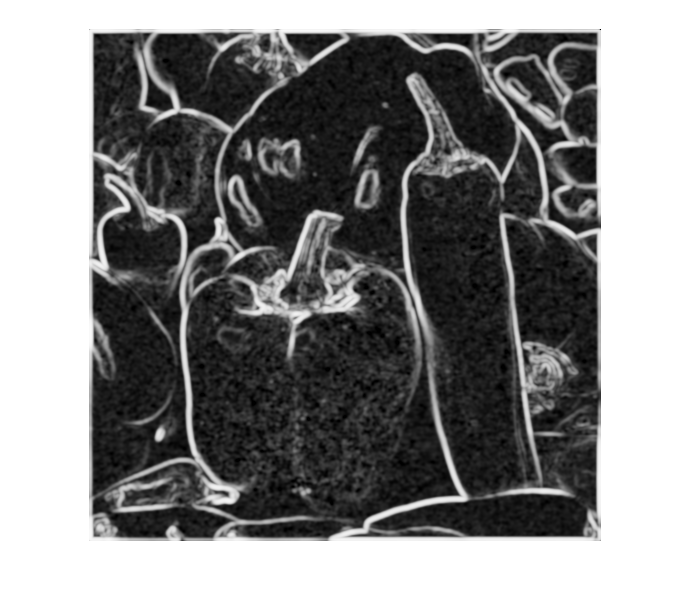

%5a
im_ssim = imread('peppers_gray.tif');
im_ssim = im2double(im_ssim);

clear a1 a2
for i = 1:size(im_ssim,1)
    
    if mod(i,2) == 0
        
        a1(i,:) = im_ssim(i,:) + 0.1;
    
    else
    
        a1(i,:) = im_ssim(i,:) - 0.1;
    
    end

end

for i = 1:size(im_ssim,1)
    
    if i>=512/2 
        
        a2(i,:) = im_ssim(i,:) + 0.1;
        
    else
        
        a2(i,:) = im_ssim(i,:) - 0.1;
        
    end
    
end

snr_a1 = snr(im_ssim, im_ssim - a1);
snr_a2 = snr(im_ssim, im_ssim - a2);

[comparison_a1, a1_ssim] = ssim(im_ssim, a1);
[comparison_a2, a2_ssim] = ssim(im_ssim, a2);

%imshow(a1_ssim)

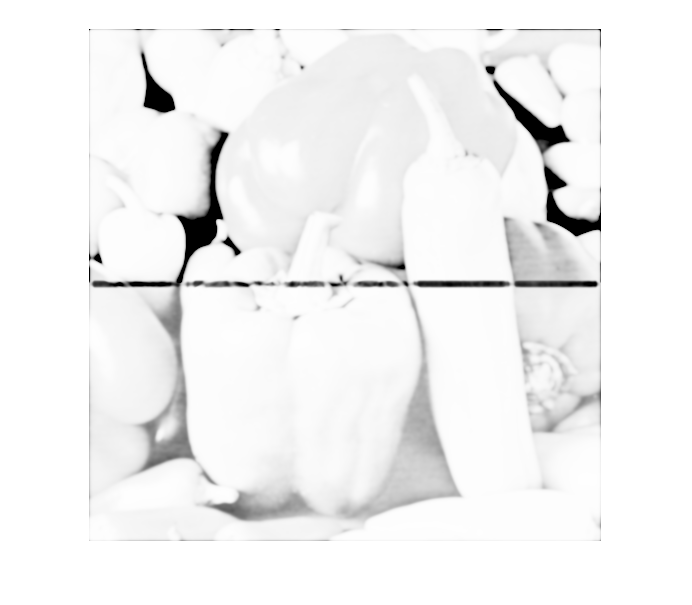

%imshow(a2_ssim)

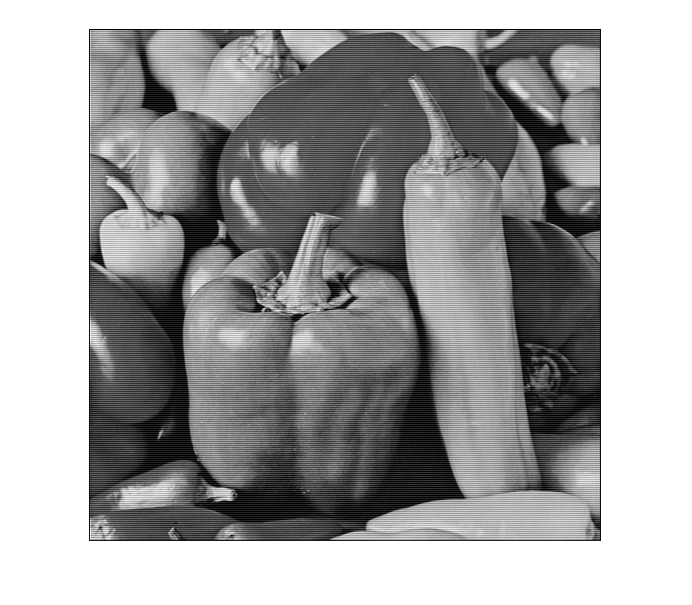


%higher ssim is better

imshow(a1)

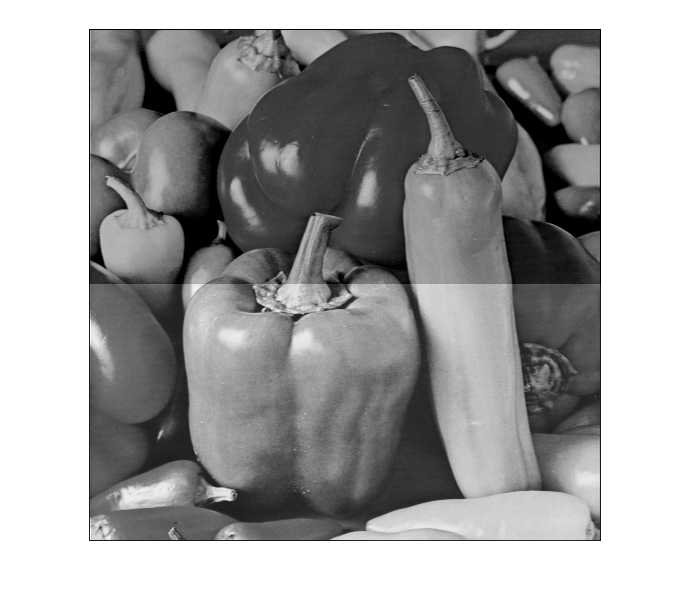

imshow(a2)

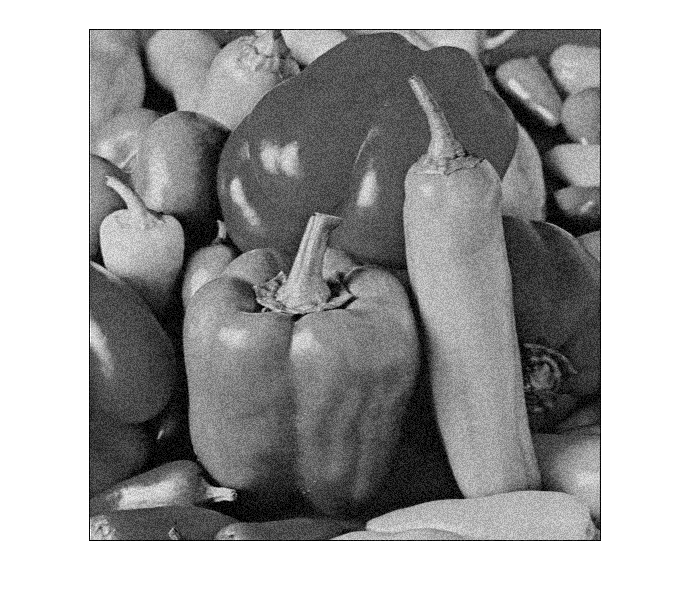

%5b
b1 = im_ssim + 0.2*(rand(size(im_ssim))-0.5);
hold off
f = fspecial('gauss', 21,10);
b2 = imfilter(im_ssim, f);
imshow(b1)

snr_b1 = snr(im_ssim, im_ssim - b1);
snr_b2 = snr(im_ssim, im_ssim - b2);

[comparison_b1, b1_ssim] = ssim(im_ssim, b1);
[comparison_b2, b2_ssim] = ssim(im_ssim, b2);
hold off

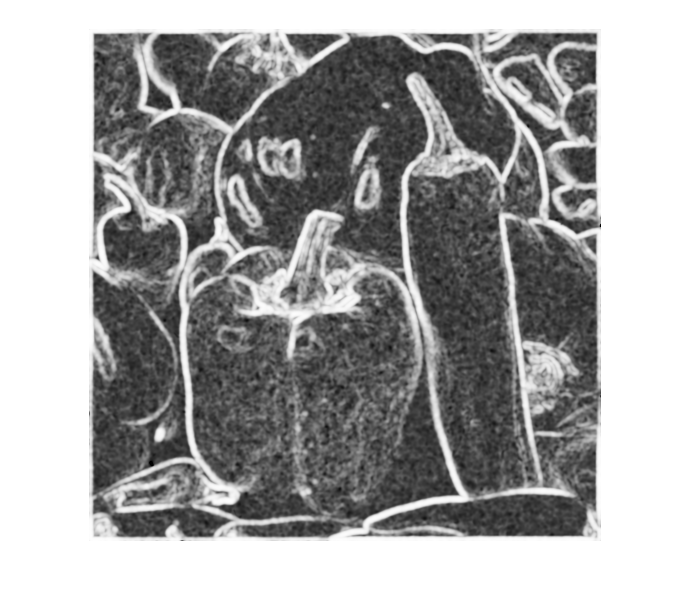

imshow(b1_ssim)

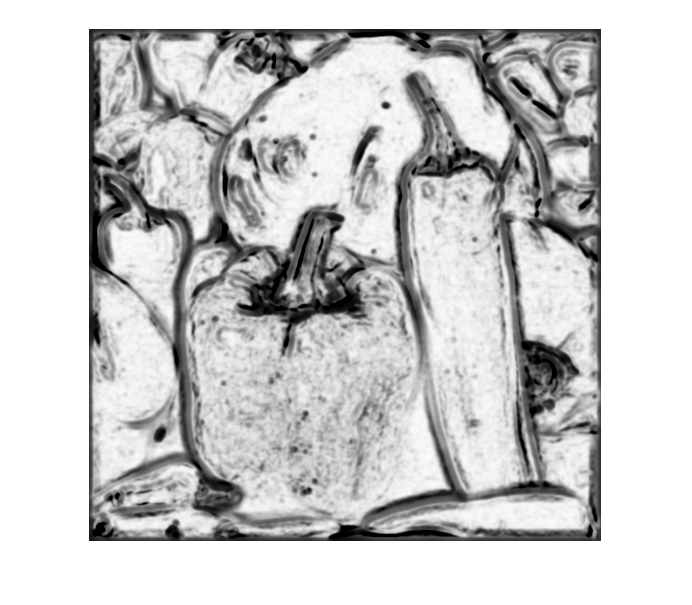

imshow(b2_ssim)